## Assignment-2:

Consider the flow over a flat plate. Take suitable grid points and store data in those points according to the field equation given and then plot the x velocity(draw vector plot) variation in the direction perpendicular to the plate at x=0m 02m and 04m. Total length of the plate is 6m. It is known that x velocity variation along y direction is given by

$\frac{u}{U_{\infty } }=\frac{3}{2}\left(\frac{y}{\delta }\right)−\frac{1}{2}{\left(\frac{y}{\delta }\right)}^3$, where $\delta$=boundary layer thickness given by the relation $\delta =\frac{5x}{\sqrt{{Re}_x }}$ 

It is known that fluid flowing over the plate is SAE15W40 oil. 

$U_{\infty }$=1m/s, density=$850\frac{kg}{m^3 }$, dynamic viscosity=$0\ldotp 155Pa\ldotp s$

Also draw the locus of the boundary layer thickness along the plate length.

## Solution: 

clear;
clc;
close all;
    % Plate Geometry
L=6; %unit m
%Flow parameters & Fluid properties
U=1; %Free stream velocity
rho=850;%density in SI
mu=0.155;% Dynamic Viscosity in SI
Re_L=rho*U*L/mu;
delta_L=5*L/(Re_L^0.5);

% Envelope geometry
lx=L;
ly=delta_L;
%Create Grid points
nx=7;
ny=15;
x_zero_plus_values=linspace(1,lx,nx);
x=[0,x_zero_plus_values];
y=linspace(0,ly,ny);

%Initialization
u(ny,nx+1)=0;
u(1:ny,1)=U;
v(ny,nx+1)=0;
delta=zeros(1,nx+1);
%No slip boundary condition
u(1,1:nx+1)=0;
% Boundary layer thickness & Velocity calculation
for i=2:nx+1
    Re_x=rho*U*x(i)/mu;
    delta(i)=5*x(i)/(Re_x^0.5);
    for j=1:ny
        if y(j)<=delta(i)
        u(j,i)=U*((3/2)*(y(j)/delta(i))-(1/2)*(y(j)/delta(i))^3);
        else 
        u(j,i)=U; 
        end
    end
end

% Plot
% Velocity Vector Plot
[X,Y]=meshgrid(x,y);
quiver(X,Y,u,v,0.5);

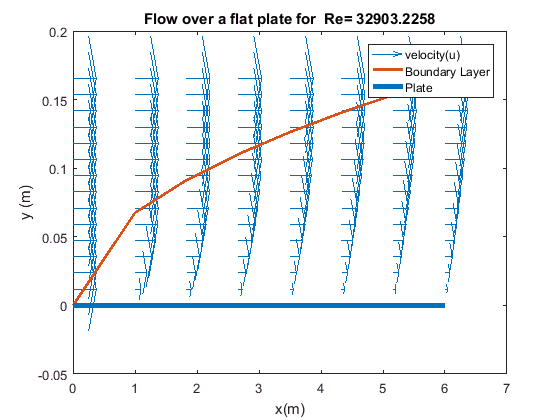

title(['Flow over a flat plate for  Re= ',num2str(Re_L)]);

hold on
% Plot Edge of the Boundary Layer
plot(x,delta,'LineWidth',2);

%Plot flat plate
line([0,L],[0,0],'LineWidth',4);
ylabel('y (m)');
xlabel('x(m)');
legend('velocity(u)','Boundary Layer','Plate');